%% Lab Flux Test Set-Point Calculations
%
% Lincoln Scheer
% 25 April 2024
%
%
% The purpose of this script is to determine MFC set-points that will
% simulate expected flux ranges in the lab environment.

clc, clear, close all

%% System Assumptions

% Chamber Surface Area
As = 0.064844702; % [m^2]

% Environment Assumptions
P = 101325; % [Pa]
T = 293.15; % [K]

% Expected Flux Ranges
F_l = 0.5; % low range [umol/m^2/s]
F_h = 10; % high range [umol/m^2/s]

% Delivery Tank Concentration
Ctank = 3003; % [ppm]

% MFC Size Used
MFC_q = 2.5; % [lpm]

% CO2 Ambient Concentration
Camb = 0; % [ppm]

% Pump Flow Rate
Q = 2; %[lpm]

% Resolution
res = 100;

% Unit Conversion Functions
ppm_to_mol = @(ppm) (ppm*P)/(1e6*8.314*T);  % ppm to mol/m^3
mol_to_ppm = @(mol) (1e6*8.314*mol*T)/P;    % mol/m^3 to ppm
lpm_to_cms = @(lpm) lpm/60000;              % liters per min to m^3 per min
cms_to_lpm = @(cms) cms*60000;              % m^3 per min to liters per min

% Chamber Concentration Steady State
Cchmb_tss = @(Camb, F, As, Q) Camb + (F.*As)./Q;

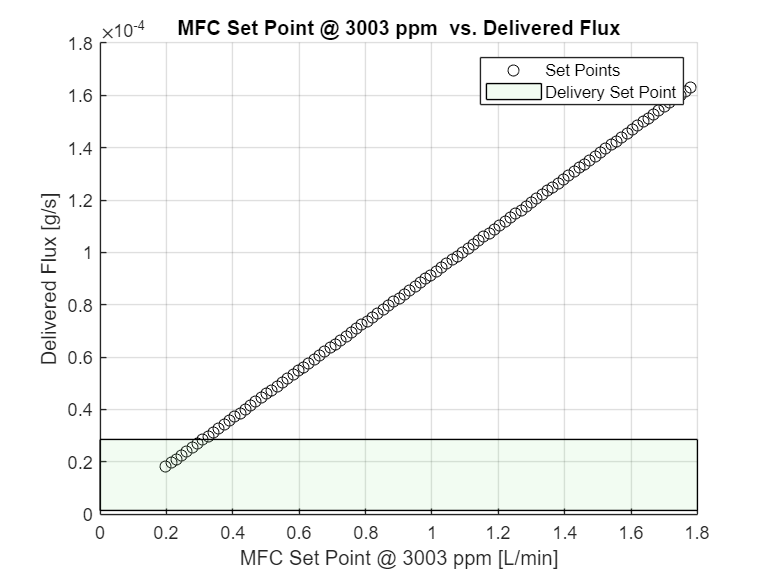

% Converting Flux Delivery from [umol/m^2/s] to [g/s]
w_F_l = F_l * 44.0095 * 1e-6 * As;
w_F_h = F_h * 44.0095 * 1e-6 * As; 

% Calculate Possible Setpoint Range % [m^3/s]
mfc_low = lpm_to_cms(MFC_q*0.1);
mfc_high = lpm_to_cms(MFC_q - MFC_q*0.1);
mfc_set_pt_rng = linspace(mfc_low, mfc_high, res);

% apply slpm to lpm conversion
load("mfc_q_calib.mat")
mfc_set_pt_rng = lpm_to_cms(cms_to_lpm(mfc_set_pt_rng)*0.791+(0.0002));

% Convert Tank Concentration from [ppm] to [g/m^3]
w_Ctank = ppm_to_mol(Ctank)*44.0096;

% Calculate Possible Delivery Range [g/s]
dlv_set_pt_rng = mfc_set_pt_rng * w_Ctank;

% Plotting Set Points vs. Delivered Flux
%
%   Green shaded area indicates desired delivered fluxes that we want, if
%   delivery set points are outside of green range, adjust the Ctank
%   concentration delivered or the MFC size used.
%
figure()
hold on
plot(cms_to_lpm(mfc_set_pt_rng), dlv_set_pt_rng, 'ko')
patch([min(xlim) max(xlim) max(xlim) min(xlim)], [w_F_l w_F_l w_F_h, w_F_h], [0.5 0.9 0.5], 'FaceAlpha', 0.1)
title("MFC Set Point @ " + Ctank + " ppm  vs. Delivered Flux")
legend(["Set Points", "Delivery Set Point"])
xlabel("MFC Set Point @ " + Ctank + " ppm [L/min]")
ylabel("Delivered Flux [g/s]")
grid on


% Creating Table
set_points = table(cms_to_lpm(mfc_set_pt_rng)', dlv_set_pt_rng', 'VariableNames', ["Set Point [sLPM]", "Delivered Flux [g/s]"]);
set_points.("Delivered Flux [g/day]") = (set_points.("Delivered Flux [g/s]")*60*60*24)/As;
set_points.("Delivered Flux [umol/m^2/s]") = ((set_points.("Delivered Flux [g/s]")./44.0095)./As)*1e6;
set_points.("Expected Chamber Steady State CO2 [ppm]") = mol_to_ppm(Cchmb_tss(ppm_to_mol(Camb), set_points.("Delivered Flux [umol/m^2/s]")*1e-6, As, lpm_to_cms(Q)))

set_points = 100×5 table
    Set Point [sLPM]    Delivered Flux [g/s]    Delivered Flux [g/day]    Delivered Flux [umol/m^2/s]    Expected Chamber Steady State CO2 [ppm]
    ________________    ____________________    ______________________    ___________________________    _______________________________________

        0.19795              1.8127e-05                 24.153                      6.3519                               297.22                 
        0.21393               1.959e-05                 26.102                      6.8647                               321.22                 
        0.22991              2.1054e-05                 28.052                      7.3774                               345.21                 
        0.24589              2.2517e-05                 30.002                 

% Apply Calibration
%load('q_calib.mat');
%set_points.("Corrected Set Point [SLPM]") = predict(Q_actual, cms_to_lpm(mfc_set_pt_rng)');

Q_total = lpm_to_cms(Q);
Q_sp = mfc_set_pt_rng;
Q_am = Q_total - Q_sp;
Css = (Ctank*Q_sp+Camb*Q_am)/(Q_total);
fprintf("%.1f\t[ppm]\n", Css)

297.2	[ppm]
321.2	[ppm]
345.2	[ppm]
369.2	[ppm]
393.2	[ppm]
417.2	[ppm]
441.2	[ppm]
465.2	[ppm]
489.2	[ppm]
513.2	[ppm]
537.2	[ppm]
561.2	[ppm]
585.1	[ppm]
609.1	[ppm]
633.1	[ppm]
657.1	[ppm]
681.1	[ppm]
705.1	[ppm]
729.1	[ppm]
753.1	[ppm]
777.1	[ppm]
801.1	[ppm]
825.1	[ppm]
849.1	[ppm]
873.1	[ppm]
897.1	[ppm]
921.1	[ppm]
945.1	[ppm]
969.0	[ppm]
993.0	[ppm]
1017.0	[ppm]
1041.0	[ppm]
1065.0	[ppm]
1089.0	[ppm]
1113.0	[ppm]
1137.0	[ppm]
1161.0	[ppm]
1185.0	[ppm]
1209.0	[ppm]
1233.0	[ppm]
1257.0	[ppm]
1281.0	[ppm]
1305.0	[ppm]
1328.9	[ppm]
1352.9	[ppm]
1376.9	[ppm]
1400.9	[ppm]
1424.9	[ppm]
1448.9	[ppm]
1472.9	[ppm]
1496.9	[ppm]
1520.9	[ppm]
1544.9	[ppm]
1568.9	[ppm]
1592.9	[ppm]
1616.9	[ppm]
1640.9	[ppm]
1664.9	[ppm]
1688.9	[ppm]
1712.8	[ppm]
1736.8	[ppm]
1760.8	[ppm]
1784.8	[ppm]
1808.8	[ppm]
1832.8	[ppm]
1856.8	[ppm]
1880.8	[ppm]
1904.8	[ppm]
1928.8	[ppm]
1952.8	[ppm]
1976.8	[ppm]
2000.8	[ppm]
2024.8	[ppm]
2048.8	[ppm]
2072.8	[ppm]
2096.7	[ppm]
2120.7	[ppm]
2144.7	[ppm]
2168.7	[ppm]
219